#                        Blind Source Separation

##                                            HW7-Section-1

                 Mohammadreza Arani         :::::::::::::         810100511

                                                           1402/02/24   

clear; clc; close all;

## Section-1:

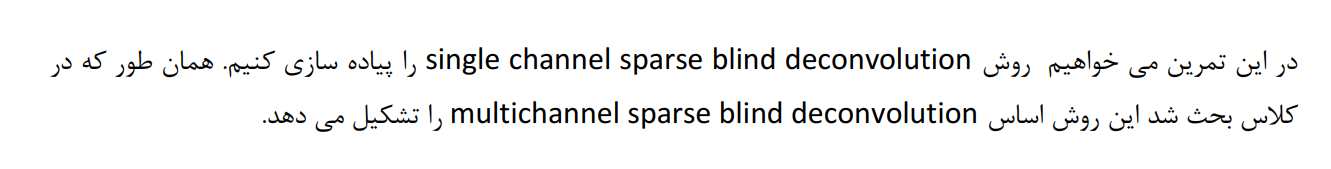

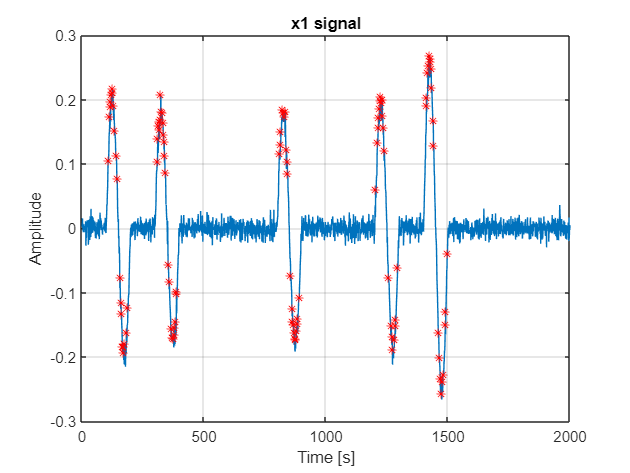

Data_hw7 = load("hw7.mat");
L = 100;
K = 5;


x1 = Data_hw7.x1;

% Find signals and their occurance

[Peaks_x1 , Locs_x1] = findpeaks(x1);

Good_Indices_Peaks =   find( (abs(Peaks_x1)>mean(abs(x1))) );


figure()
plot(x1)
grid on
xlabel("Time [s]")
ylabel("Amplitude")
title("x1 signal")
hold on
plot(Locs_x1(Good_Indices_Peaks),Peaks_x1(Good_Indices_Peaks),'r*')

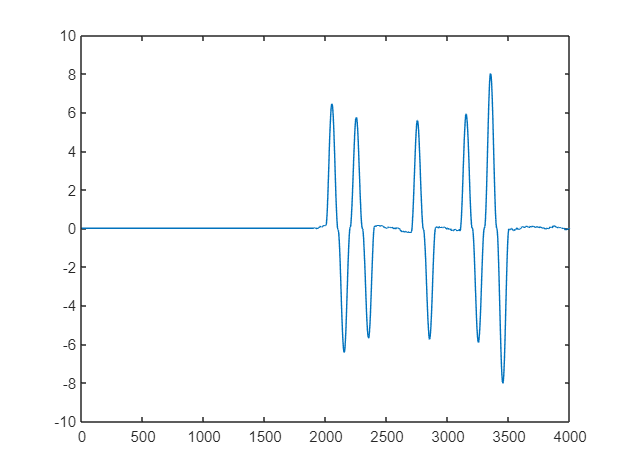

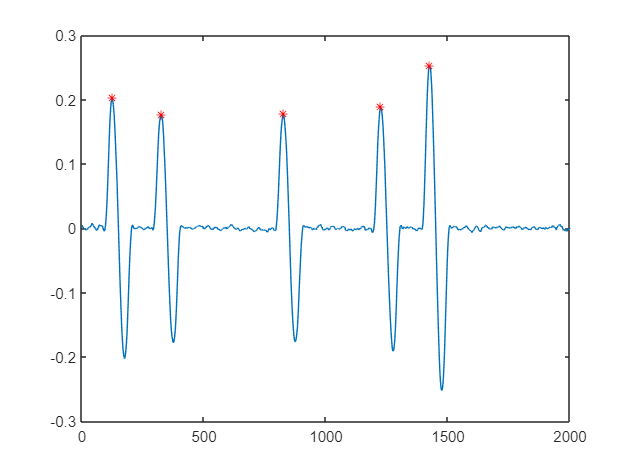

windowSize = 31;
polyOrder = 2;
y1 = sgolayfilt(x1, polyOrder, windowSize);
figure()
plot(y1)
[Peaks_y1 , Locs_y1] = findpeaks(y1);

Good_Indices_Peaks =   find( ((Peaks_y1)>mean(abs(y1))) );
hold on
plot(Locs_y1(Good_Indices_Peaks),Peaks_y1(Good_Indices_Peaks),'r*')
hold off

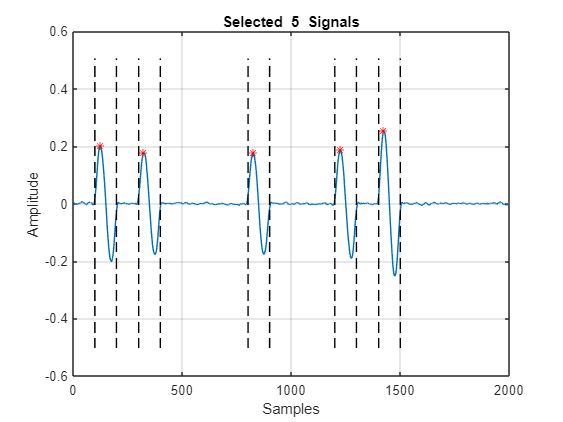


figure()
plot(y1)


[Peaks_y1 , Locs_y1] = findpeaks(y1);

Good_Indices_Peaks =   find( ((Peaks_y1)>mean(abs(y1))) );
hold on
plot(Locs_y1(Good_Indices_Peaks),Peaks_y1(Good_Indices_Peaks),'r*');

% Loc_target_k = zeros(1,K);
Loc_target_k = Locs_y1(Good_Indices_Peaks);
Selected_Indices = zeros(2,K) ;
Signal_Selected_k = zeros(L,K);

for k=1:K
    Signal_Selected_k(:,k) = x1(Loc_target_k(1,k)-L/4+1:Loc_target_k(1,k)+3*L/4);
    Selected_Indices(:,k) = [ Loc_target_k(1,k)-L/4+1 ; Loc_target_k(1,k)+3*L/4 ];
    plot(Selected_Indices(1,k)*ones(1,10),linspace(-2*abs(min(y1)),2*max(abs(y1)),10)  ,'black--' );
    plot(Selected_Indices(2,k)*ones(1,10),linspace(-2*abs(min(y1)),2*max(abs(y1)),10)  ,'black--' );

end
grid on
title("Selected  "+K+"  Signals");
xlabel("Samples")
ylabel("Amplitude")
hold off

## Single Channel---> Step-1: Having "shai" Fixed --->Step-2: Having "S" Fixed

disp(char(hex2dec('0428'))+"(t) is fixed & then S is Fixed");

Ш(t) is fixed & then S is Fixed


IterMax=50;
rng(1);
Alpha_vec = randn(K,1);
Z = buffer(y1 ,L, L-1 ,'nodelay');
T = length(y1);
y_hat = zeros(size(y1));
for i=1:IterMax
    % Step-1: Shai is fixed
    S_hat_time = Signal_Selected_k*pinv(Alpha_vec');
    % Normalize S hat
    S_hat_time = S_hat_time/norm(S_hat_time);
    % Step-2:  S is fixed
    Chosen_Index_Z = zeros(1,K);
    temp_Z = Z;
    b = zeros(1,T);
    for k=1:K
       [~,index_max]  = max(   abs( S_hat_time'*temp_Z  ));
       Chosen_Index_Z(1,k) = index_max;
       if(index_max-L/4+1<0)
        Index_to_Change = 1:L;
       else
        Index_to_Change = index_max-L/4+1:index_max+3*L/4;
       end
       b(1,index_max) =  S_hat_time'*temp_Z(:,index_max)/( S_hat_time'*S_hat_time  );
       Alpha_vec(k,1) = b(1,index_max);
       Signal_Selected_k(:,k) = y1(Index_to_Change)  ;%Chosen_Index_Z(1,k)-L/4+1:Chosen_Index_Z(1,k)+3*L/4
       y_hat(1,Index_to_Change) = Signal_Selected_k(:,k);
       temp_Z(:, Index_to_Change ) = 0;
    end
end

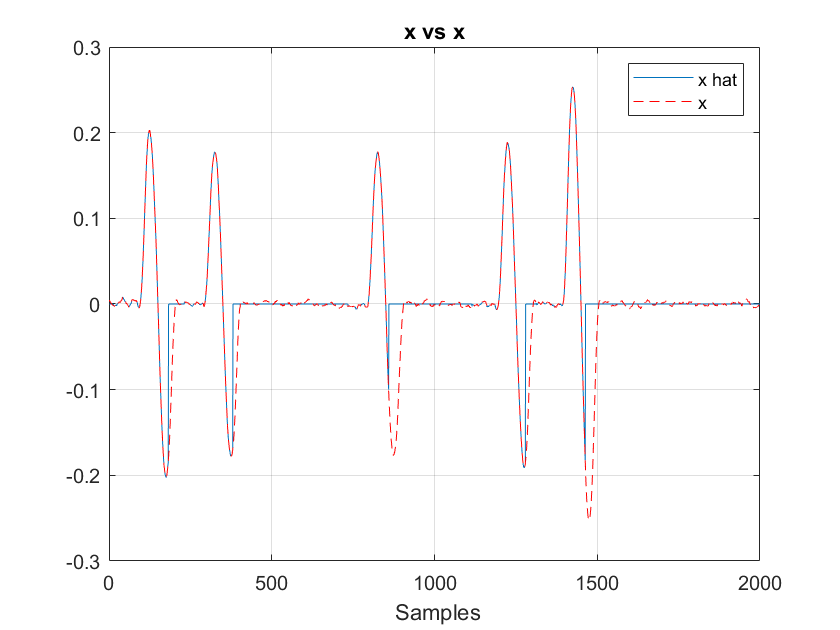


figure()
plot(y_hat);
grid on
hold on
plot(y1,'r--');
title("x^ vs x")
xlabel(" Samples")
legend("x hat" , "x");
hold off

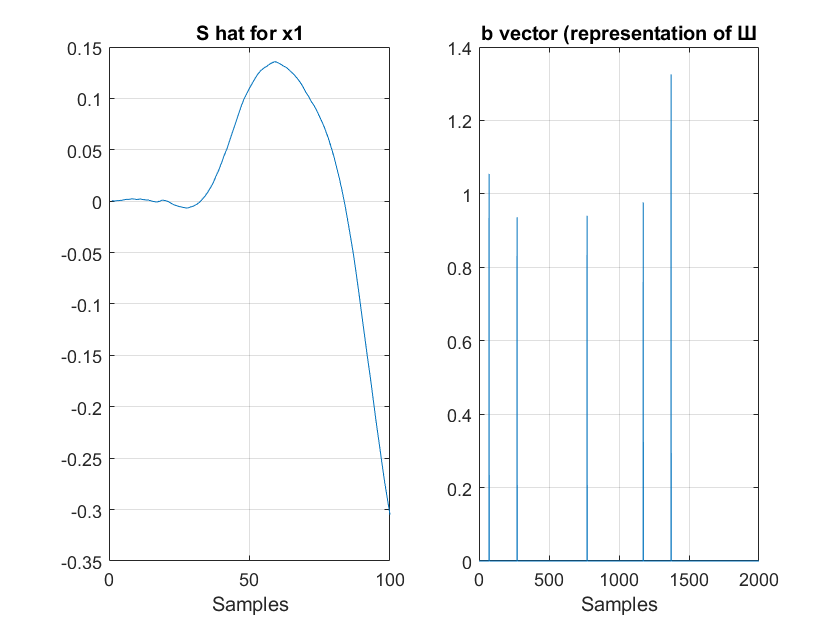




% Plot S hat for x2:
figure()
subplot(1,2,1)
plot(S_hat_time)
xlabel("Samples")
grid on
title("S hat for x1")

subplot(1,2,2)
plot(b)
xlabel("Samples")
grid on
title("b vector (representation of "+char(hex2dec('0428')))

## Repeat for x2:

x2 = Data_hw7.x2;

windowSize = 35;
polyOrder = 2;
y2 = sgolayfilt(x2, polyOrder, windowSize);

figure()
plot(y2)
[Peaks_y2 , Locs_y2] = findpeaks(y2);

Good_Indices_Peaks =   find( ((Peaks_y2)>mean(abs(y2))) );
hold on
plot(Locs_y2(Good_Indices_Peaks),Peaks_y2(Good_Indices_Peaks),'r*');

% Loc_target_k = zeros(1,K);
Loc_target_k = Locs_y2(Good_Indices_Peaks);
Selected_Indices = zeros(2,K) ;
Signal_Selected_k = zeros(L,K);

for k=1:K
    Signal_Selected_k(:,k) = x2(Loc_target_k(1,k)-L/4+1:Loc_target_k(1,k)+3*L/4);
    Selected_Indices(:,k) = [ Loc_target_k(1,k)-L/4+1 ; Loc_target_k(1,k)+3*L/4 ];
    plot(Selected_Indices(1,k)*ones(1,10),linspace(-2*abs(min(y1)),2*max(abs(y1)),10)  ,'black--' );
    plot(Selected_Indices(2,k)*ones(1,10),linspace(-2*abs(min(y1)),2*max(abs(y1)),10)  ,'black--' );

end

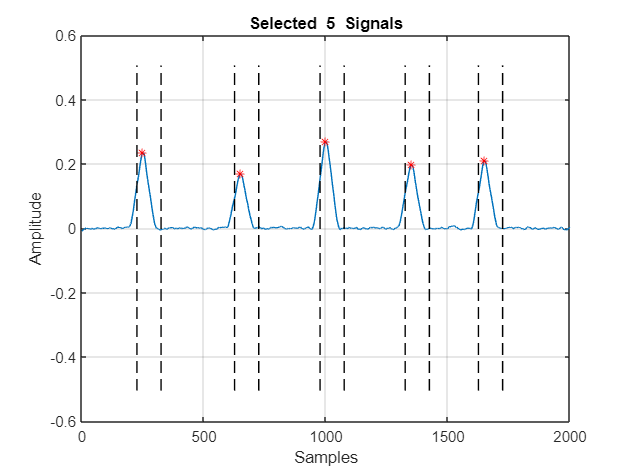


grid on
title("Selected  "+K+"  Signals");
xlabel("Samples")
ylabel("Amplitude")
hold off



disp(char(hex2dec('0428'))+"(t) is fixed & then S is Fixed");

Ш(t) is fixed & then S is Fixed


IterMax=10;
Alpha_vec = randn(K,1);
Z = buffer(y2 ,L, L-1 ,'nodelay');
T = length(y2);
y_hat_2 = zeros(size(y2));

for i=1:IterMax
    % Step-1: Shai is fixed
    S_hat_time = Signal_Selected_k*pinv(Alpha_vec');
    % Normalize S hat
    S_hat_time = S_hat_time/norm(S_hat_time);
    % Step-2:  S is fixed
    Chosen_Index_Z = zeros(1,K);
    temp_Z = Z;
    b = zeros(1,T);
    for k=1:K
       [~,index_max]  = max(   abs( S_hat_time'*temp_Z  ));
       Chosen_Index_Z(1,k) = index_max;
       if(index_max-L/4+1<0)
        Index_to_Change = 1:L;
       else
        Index_to_Change = index_max-L/4+1:index_max+3*L/4;
       end
       b(1,index_max) =  S_hat_time'*temp_Z(:,index_max)/( S_hat_time'*S_hat_time  );
       Alpha_vec(k,1) = b(1,index_max);
       Signal_Selected_k(:,k) = y2(Index_to_Change)  ;%Chosen_Index_Z(1,k)-L/4+1:Chosen_Index_Z(1,k)+3*L/4
       y_hat_2(1,Index_to_Change) = Signal_Selected_k(:,k);
       temp_Z(:, Index_to_Change ) = 0;
    end
end

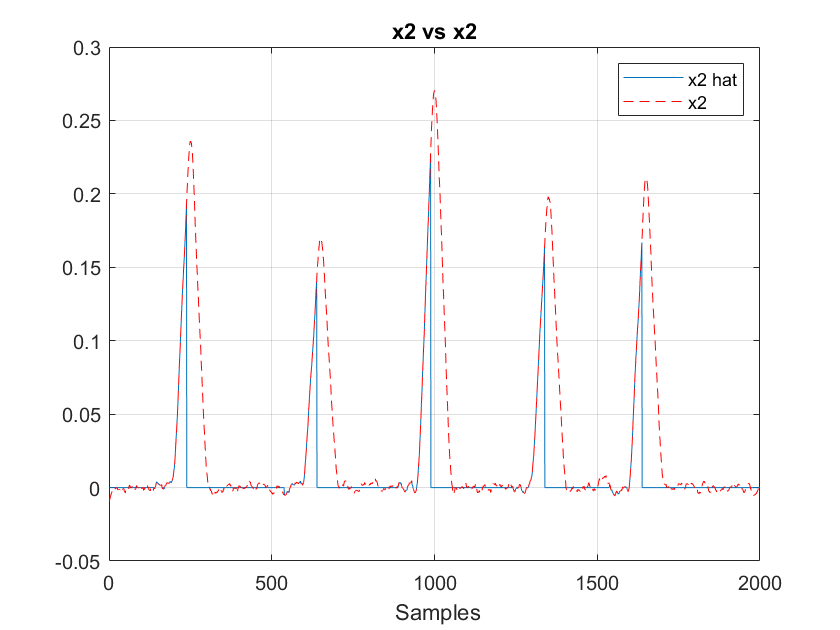


figure()
plot(y_hat_2);
grid on
hold on
plot(y2,'r--');
title("x2^ vs x2")
xlabel(" Samples")
legend("x2 hat" , "x2");
hold off

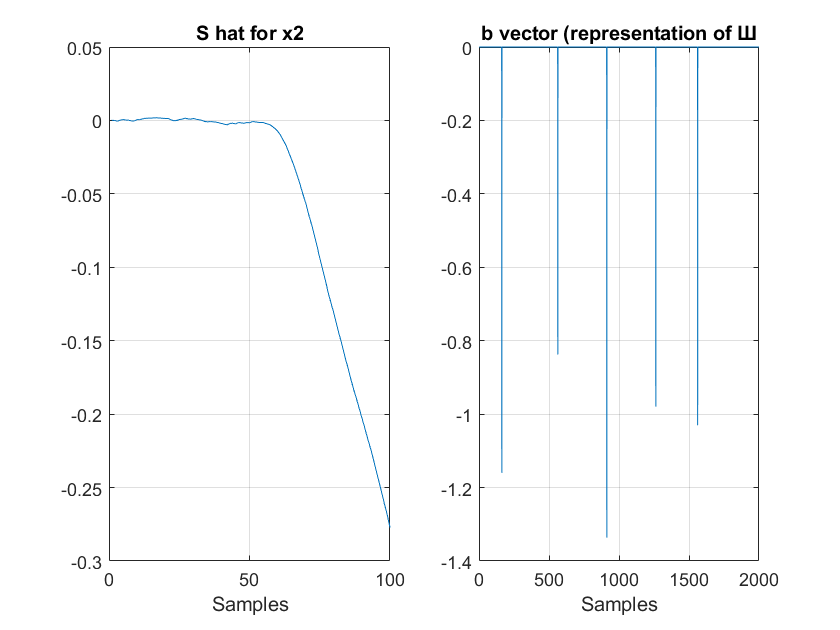


% Plot S hat for x2:
figure()
subplot(1,2,1)
plot(S_hat_time)
xlabel("Samples")
grid on
title("S hat for x2")

subplot(1,2,2)
plot(b)
xlabel("Samples")
grid on
title("b vector (representation of "+char(hex2dec('0428')))

## Part-3:

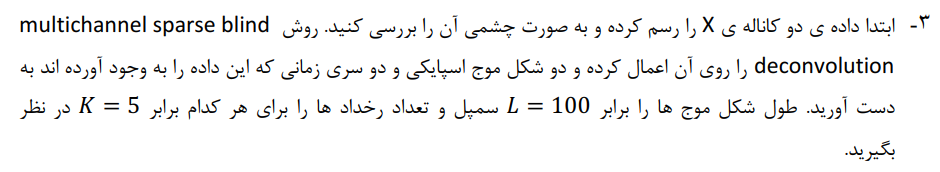

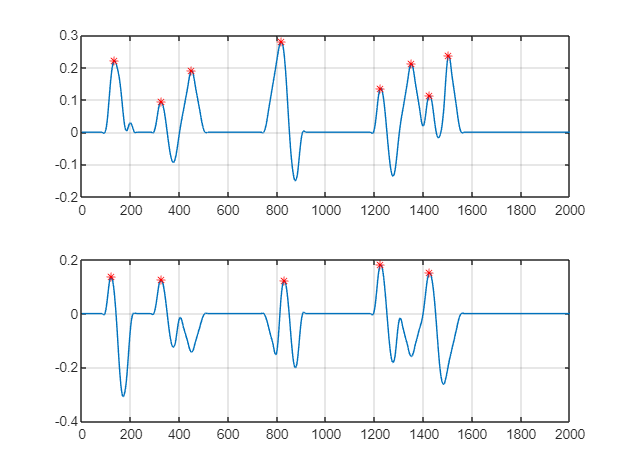

X = Data_hw7.X;
windowSize = 35;
polyOrder = 2;
y_X1 = sgolayfilt(X(1,:), polyOrder, windowSize);
y_X2 = sgolayfilt(X(2,:), polyOrder, windowSize);

figure()
subplot(2,1,1)
plot(y_X1)
[Peaks_y , Locs_y] = findpeaks(y_X1);
Good_Indices_Peaks =   find( ((Peaks_y)>mean(abs(y_X1))) );
hold on
plot(Locs_y(Good_Indices_Peaks),Peaks_y(Good_Indices_Peaks),'r*');
hold off
grid on
subplot(2,1,2)
plot(y_X2)
[Peaks_y , Locs_y] = findpeaks(y_X2);
Good_Indices_Peaks =   find( ((Peaks_y)>mean(abs(y_X2))) );
hold on
plot(Locs_y(Good_Indices_Peaks),Peaks_y(Good_Indices_Peaks),'r*');
hold off
grid on


IterMax = 2;
X = Data_hw7.X;
[Row_X , Col_x] = size(X);
K = 5;
L=100;
% Generate Random A Matrix:

A   = randn(Row_X);
A   = normalize(A, 'norm', 2) ;  % Normalize Columns of A

IterMax_2 = 50;
Rep_Error = zeros(1,IterMax_2);
best_Rep_Err = inf;
for i=1:IterMax_2

    S_hat =  A\X;

    y_hat_Xj = zeros(Row_X,T) ;
    b_Xj     = zeros(Row_X,T) ;
    S_hat_time_Xj = zeros(Row_X,L);



    for j=1:Row_X
            flip = 0;
            if ( abs(min(S_hat(j,:)))>abs(max(S_hat(j,:)))  )
                S_hat(j,:) = -S_hat(j,:);
                flip = 1;
            end
            [ y_hat_Xj(j,:) , b_Xj(j,:) , S_hat_time_Xj(j,:) ]  = Single_Ch_Time_Dec(S_hat(j,:),IterMax,K,L);
            if(flip)
                y_hat_Xj(j,:)  = -y_hat_Xj(j,:) ;
                b_Xj(j,:)  = -b_Xj(j,:) ;
                S_hat_time_Xj(j,:)  = -S_hat_time_Xj(j,:) ;
            end
        % S_hat(j,:)  = conv( b_Xj(j,:) , S_hat_time_Xj,"same" )  ;
    end
    % S_hat = [conv(Si1,S1_hat,'same');conv(Si2,S2_hat,'same')];
    S_hat = y_hat_Xj;

    % Step-2: S is fixed --> FInd A:
    A = X*pinv(S_hat);
    A   = normalize(A, 'norm', 2) ; 

    % Calculate the Representation Error:
    Rep_Error(1,i) = norm( X-A*S_hat ,"fro" );
    if (abs(Rep_Error(1,i) - mean(Rep_Error(1,1:i))) < 1e-3 ) && (i>5) % Convergence Happens
        break;
    elseif( Rep_Error(1,i)< best_Rep_Err )
        best_Rep_Err = Rep_Error(1,i);
        Best_Index_Rep_Err = i;
        Best_S_hat = S_hat;
        Best_b_vec = b_Xj ;
        Best_S_hat_k = S_hat_time_Xj;
    end
end


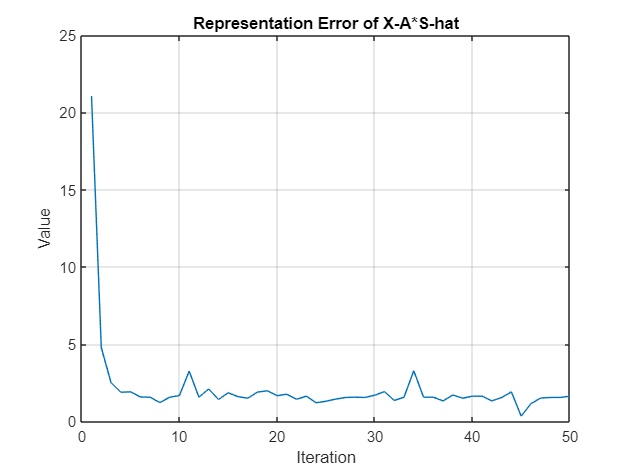


figure()
plot( 1:length(Rep_Error), Rep_Error);
grid on
title("Representation Error of X-A*S-hat")
xlabel("Iteration")
ylabel("Value")

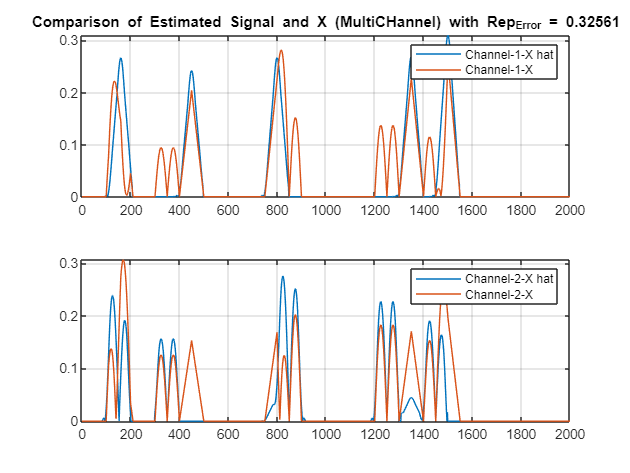


figure()
subplot(2,1,1)
plot(abs(Best_S_hat(2,:)))
hold on
plot(abs(X(1,:)))
hold off
grid on
title("Comparison of Estimated Signal and X (MultiCHannel) with Rep_{Error} = "+best_Rep_Err)
legend("Channel-1-X hat", "Channel-1-X")

subplot(2,1,2)
plot(abs(Best_S_hat(1,:)))
hold on
plot(abs(X(2,:)))
hold off
grid on
legend("Channel-2-X hat", "Channel-2-X")

## Functions:

function  [ y_hat , b, S_hat_time ]  = Single_Ch_Time_Dec(x,IterMax,K,L)

T = length(x);
% Smooth the Input:
windowSize = 35;
polyOrder = 2;
y = sgolayfilt(x, polyOrder, windowSize);

% figure()
% plot(y)
[Peaks_y , Locs_y] = findpeaks(y);

Good_Indices_Peaks =   find( ((Peaks_y)>mean(abs(y))) );
% hold on
% plot(Locs_y(Good_Indices_Peaks),Peaks_y(Good_Indices_Peaks),'r*');

% Loc_target_k = zeros(1,K);
Loc_target_k = Locs_y(Good_Indices_Peaks);
Signal_Selected_k = zeros(L,K);
cntr = 1;
Indexes_to_remove =[];

for i=2:length(Loc_target_k)
    if(Loc_target_k(1,i) - Loc_target_k(1,i-1)<L)
        Indexes_to_remove(cntr) = i;
        cntr = cntr+1;
    end
end
Loc_target_k(Indexes_to_remove) = [];
Indexes_to_remove =[];
% CHoose Randomly K of found occurences:
if (length(Loc_target_k)>K)
    Indexes_to_remove = randperm(length(Loc_target_k),length(Loc_target_k)-K);
    Loc_target_k(Indexes_to_remove) = [];
else
    
    if(Loc_target_k(1,end)+1.5*L < T )
        Loc_target_k(1,end+1) =  Loc_target_k(1,end)+1.5*L ;
    elseif( Loc_target_k(1,end)-1.5*L - Loc_target_k(1,end-1) > L   )
        Loc_target_k(1,end+1) = Loc_target_k(1,end)-1.5*L;
    elseif (Loc_target_k(1,1)>2*L)
        Loc_target_k(1,end+1) = Loc_target_k(1,1)-L;
    end
    Loc_target_k = sort(Loc_target_k);
    num_to_add = K - length(Loc_target_k);

    if(num_to_add>0)
        for i=1:num_to_add
            diff_vector =  diff(Loc_target_k) ;
            Possible_Candidate_to_Insert_Next_To =  find(diff_vector>L);
            Loc_target_k(1,end+1) =  Loc_target_k(Possible_Candidate_to_Insert_Next_To(1,end))-L;
            Loc_target_k = sort(Loc_target_k);
        end
    end
end

for k=1:K
    Signal_Selected_k(:,k) = x(Loc_target_k(1,k)-L/4+1:Loc_target_k(1,k)+3*L/4);
end



% IterMax=10;
Alpha_vec = randn(K,1);
Z = buffer(y ,L, L-1 ,'nodelay');
T = length(y);
y_hat= zeros(size(y));

for i=1:IterMax
    % Step-1: Shai is fixed
    S_hat_time = Signal_Selected_k*pinv(Alpha_vec');
    % Normalize S hat
    S_hat_time = S_hat_time/norm(S_hat_time);
    % Step-2:  S is fixed
    Chosen_Index_Z = zeros(1,K);
    temp_Z = Z;
    b = zeros(1,T);
    for k=1:K
       [~,index_max]  = max(   abs( S_hat_time'*temp_Z  ));
       Chosen_Index_Z(1,k) = index_max;
       if(index_max-L/4+1<0)
        Index_to_Change = 1:L;
       else
        Index_to_Change = index_max-L/4+1:index_max+3*L/4;
       end
       b(1,index_max) =  S_hat_time'*temp_Z(:,index_max)/( S_hat_time'*S_hat_time  );
       Alpha_vec(k,1) = b(1,index_max);
       Signal_Selected_k(:,k) = y(Index_to_Change)  ;%Chosen_Index_Z(1,k)-L/4+1:Chosen_Index_Z(1,k)+3*L/4
       y_hat(1,Index_to_Change) = Signal_Selected_k(:,k);
       temp_Z(:, Index_to_Change ) = 0;
    end
end


end






